## 2. Caixa com dinheiro

a) Espaço amostragem

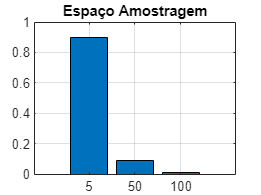

prob_5 = 90/100;
prob_50 = 9/100;
prob_100 = 1/100;

probabilidades = [prob_5, prob_50, prob_100];
x = ["5", "50","100"];
bar(probabilidades);
xticks(1:3);
xticklabels(x);
title('Espaço Amostragem')

grid on

b) Função massa

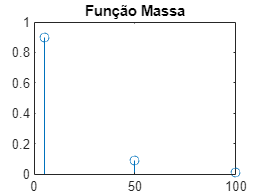

%espaço de amostragem
amostragem = [5,50,100];

%funcao massa atribui uma probabilidade a cada valor
probabilidades = [0.9,0.09,0.01];

%mostrar 
stem(amostragem,probabilidades);
title('Função Massa');

c) Função distribuição acumulada

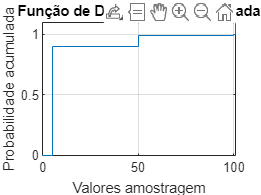

%acumulada
cdf = cumsum(probabilidades);

%plot da função
%stairs(amostragem, cdf)
%stairs mais bonitas |
stairs([0,amostragem, 101], [0, cdf, 1.1])
axis([0,101,0,1.1]);
xlabel('Valores amostragem');
ylabel('Probabilidade acumulada');
title('Função de Distribuição Acumulada')
grid on;